# **Long-term time-series forecasting**

## *1. Introduction*

The aim of this project is to identify an annual profile model for the long-term forecast of the time-series. 

More specifically the process is refered to gas consumption in Italy, in two different year, in function of a day of the week and a day of an year.

Finally, once identified the best model we've to create a function which predict the gas consumption in function of two parameters (day of the week, day of the year).

## ***2. Process visualization***

Before starting identifing the best model, it can be useful to have some idea on the process function characteristics. 

To underline those one we've plotted the process in two different ways: 

- 2D:  gas consumption in function of the day of the year;

- 3D: gas consumption in function of the day of the year, and the day of the week.

### 2.1 Plotting 2D

Before plotting it can be useful to save both years information in two different variables.

% Save the table information in two dataset, each for a year
% selecting only the data I’m interested viewing
dsYear1=readtable('../Dataset/gasITAday.xlsx', 'Range', 'A3:C367');
dsYear2=readtable('../Dataset/gasITAday.xlsx', 'Range', 'A368:C732');

% Change the coloumn's name in the different datasets
dsYear1.Properties.VariableNames{1}='DayOfTheYear';
dsYear1.Properties.VariableNames{2}='DayOfTheWeek';
dsYear1.Properties.VariableNames{3}='GasConsumption';

dsYear2.Properties.VariableNames{1}='DayOfTheYear';
dsYear2.Properties.VariableNames{2}='DayOfTheWeek';
dsYear2.Properties.VariableNames{3}='GasConsumption';

Now we can visualize both years data in different plots.

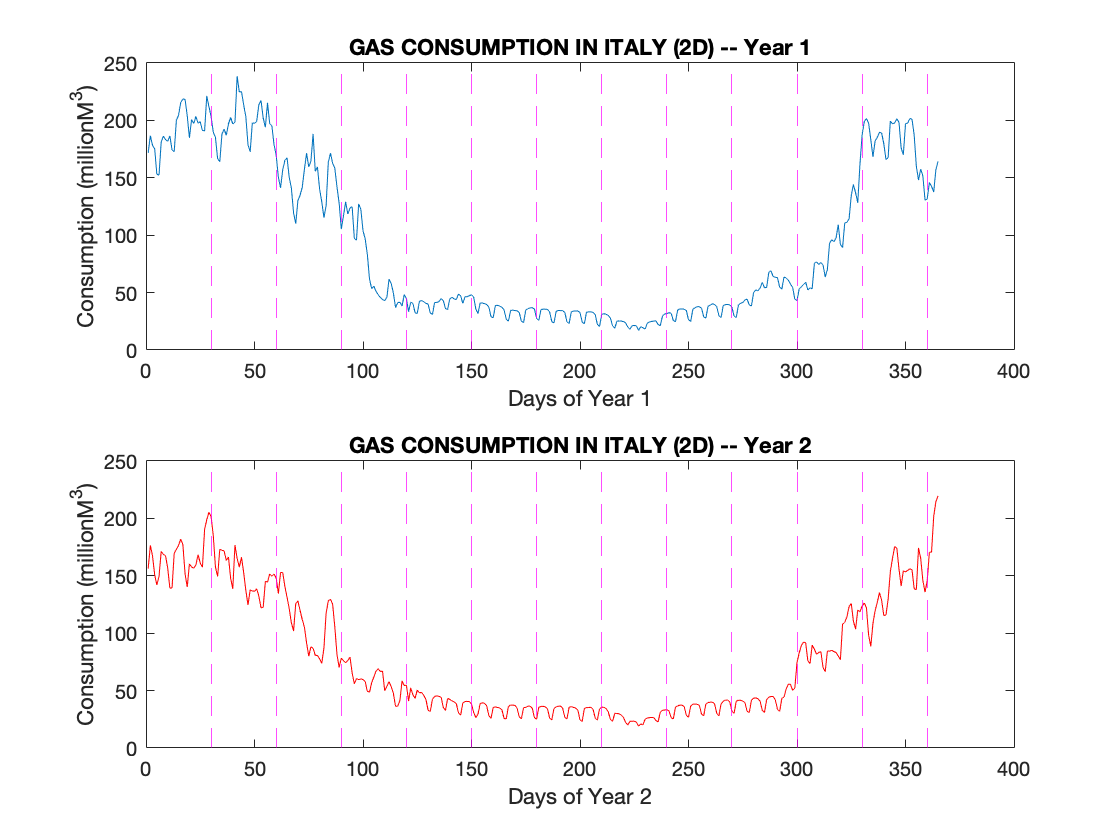

figure()
%Year 1
subplot(2,1,1)
plot(dsYear1.DayOfTheYear,dsYear1.GasConsumption);
title('GAS CONSUMPTION IN ITALY (2D) -- Year 1');
xlabel('Days of Year 1');
ylabel('Consumption (millionM^3)');
% Added vertical lines to see better the different months gas consumption
for i = 1:12
       xline(i*30, 'm--');
end
%Year 2
subplot(2,1,2)
plot(dsYear2.DayOfTheYear,dsYear2.GasConsumption,'r');
title('GAS CONSUMPTION IN ITALY (2D) -- Year 2');
xlabel('Days of Year 2');
ylabel('Consumption (millionM^3)');
% Added vertical lines to see better the different months gas consumption
for i = 1:12
       xline(i*30, 'm--');
end

*FIRST OBSERVATION:*

From the diagrams we can already notice that the gas consumption decreases in the hottest months of the year, more specifically in the days that go from the 120th (April) to the 290th (September). So we can say that this trend are both seasonal, with a periodicity of about 6 months.

*WHY THIS HAPPENS (QUITE OBVIOUS)? *

Natural gas consumption has two seasonal peaks, largely reflecting weather-related fluctuations in energy demand. In the winter months, cold weather leads to more demand for heating in the residential and commercial sectors. In the summer months, warm weather leads to more demand for air conditioning and, in turn, more demand for electricity.

*ANOTHER OBSERVATION:*

Considered a specific weekly window (7 days), we can see that during the weekends the gas consumption is lower than the other 5 days of that same week. Maybe it's due to the fact that factories during weekend are closed, so the gas consumption is less (expecially on sunday).

With this code we want to proof what we're saying, being taking a random week:

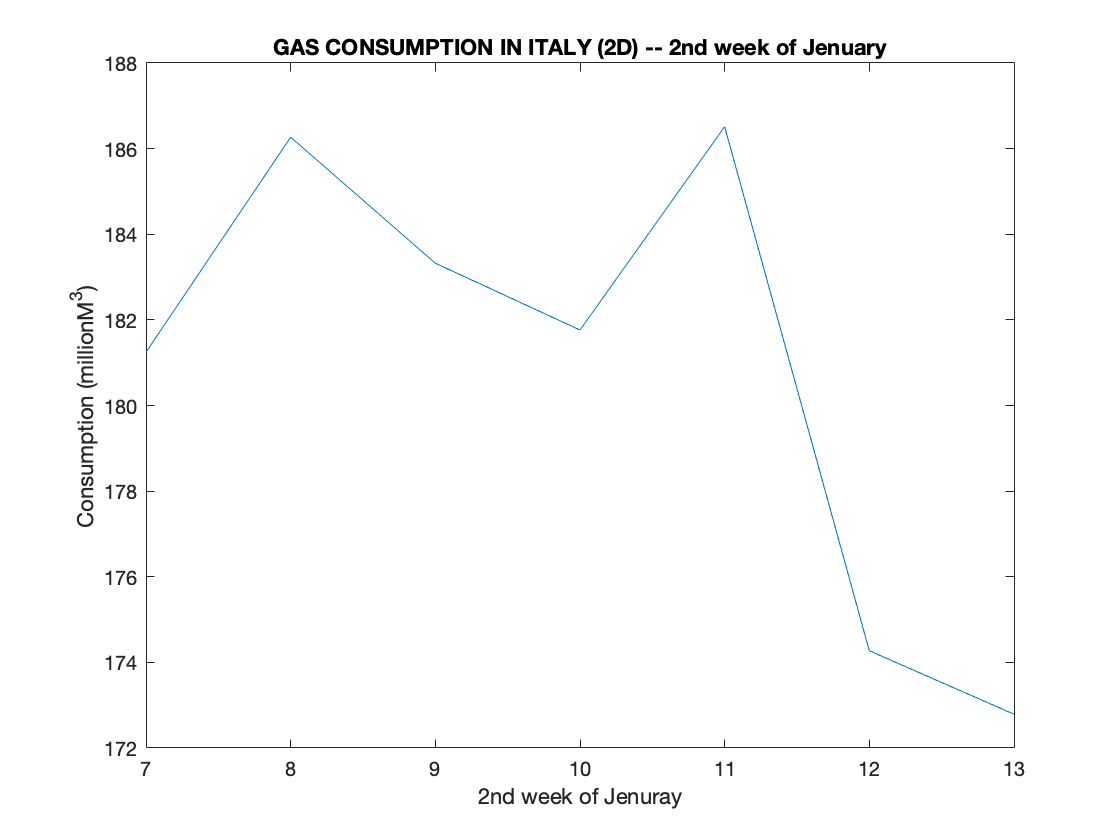

figure()
% Notice that 7 is monday, 13 is Sunday
plot(dsYear1.DayOfTheYear(7:13),dsYear1.GasConsumption(7:13));
title('GAS CONSUMPTION IN ITALY (2D) -- 2nd week of Jenuary');
xlabel('2nd week of Jenuray');
ylabel('Consumption (millionM^3)');

*SOME MATHEMATICAL OBSERVATiONS: *

We can notice that it is a [discrete time](https://en.wikipedia.org/wiki/Discrete_time_and_continuous_time) [stationary](https://en.wikipedia.org/wiki/Stationary_process) process.

Stationary as if we took two sufficiently distant windows we can see that the trend seems to be similar (except for small oscillations due to noise), more specifically if we consider windows spaced 6 months concatenating the two years (taking December of year 1 and chaining it with January of year 2). 

Discrete time because the realizations have been taken only once a day for a year and not for every moment of time of every day of a year (reasonable enough because we do not care to know the gas consumption per second, but in a whole day). 

Another quite markable characteristic is that the process is [ergodic](https://en.wikipedia.org/wiki/Ergodic_process) beacuse:  *"its statistical properties can be deduced from a single, sufficiently long, random sample of the process. The reasoning is that any collection of random samples from a process must represent the average statistical properties of the entire process. In other words, regardless of what the individual samples are, a birds-eye view of the collection of samples must represent the whole process. Conversely, a process that is not ergodic is a process that changes erratically at an inconsistent rate ".*

Finally we can say that its [autocovariance function](https://en.wikipedia.org/wiki/Autocovariance) will be centered around an average value (average gas consumption in a year, which corresponds to the sum of daily gas consumption in a year / the number of days in a year), and will have a fairly slow decline (because it remains positive for 6 months, then it goes down). So its Fourier transform (of the autocovariance) will be a fairly "fat" and "low" Gaussian (slow decay and always centered around the average value previously mentioned).

### 2.1 Plotting 3D

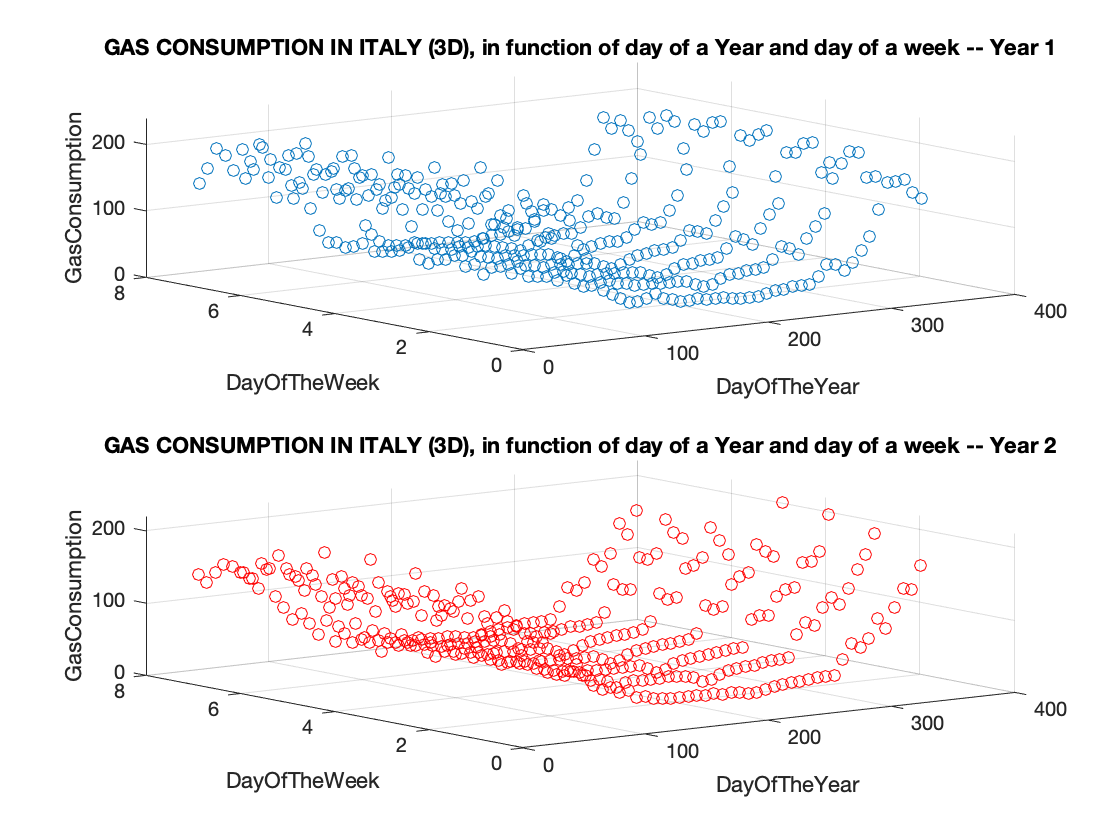

figure()
%Year 1
subplot(2,1,1)
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek,dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
%Year 2
subplot(2,1,2)
plot3(dsYear2.DayOfTheYear,dsYear2.DayOfTheWeek,dsYear2.GasConsumption,'ro');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 2');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');

## ***3. Model identification***

## ***4. Prediction function***

## ***5. Conclusion***